# Actividad 6.2 (Comparación de Algoritmos de Control)

## Resumen

Para facilitar la comparación visual entre los distintos algoritmos de control y observar el recorrido completo del robot, se realizo este código facilitado por el profesor durantre clase. Esto generó una visualización acumulativa del movimiento del robot, útil para analizar su comportamiento durante toda la trayectoria.

## Introducción

Usando estos tipos de control para el seguimiento de trayectorias se plantea observar, analizar y entender en su totalidad las fortalezas y debilidades de cada tipo:

Control en lazo abierto: sin retroalimentación sensorial. 

Control de posici´on con fases de giro y avance. 

Control de trayectoria con interpolación y retroalimentación. 

La trayectoria objetivo consiste en los siguientes puntos: (0, 0) → (−9, 10) → (−7, 1) → (−2, −10) → (3, 1) → (5, 10) → (−9, 10) 

## Resultados

A continuación, se muestra una tabla comparativa de las fortelzas y debilidades de cada tipo medido en los resultados.

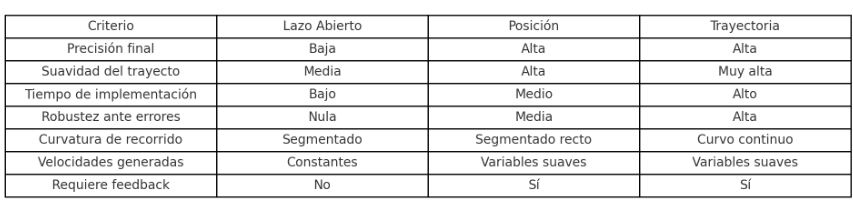

## Conclusión

En esta actividad probamos tres formas distintas de controlar el movimiento del robot: lazo abierto, control por posición y control por trayectoria. El control en lazo abierto fue el más sencillo de usar, ya que no necesita medir lo que pasa en tiempo real, solo ejecuta los movimientos programados. Sin embargo, también fue el menos preciso y el que más errores cometió, porque no se adapta si algo sale mal. Además, sus trayectorias fueron en tramos rectos con velocidades constantes, lo que hace que se vea menos fluido.

En cambio, los controles que sí usan retroalimentación funcionaron mucho mejor. El de posición ya es más inteligente, porque se orienta y avanza hacia cada punto corrigiendo errores, logrando buen nivel de precisión. Por último, el control de trayectoria fue el más completo, ya que no solo sigue los puntos, sino que lo hace con movimientos más suaves y continuos, pareciendo más natural. Aunque fue el más complicado de implementar, también fue el que dio los mejores resultados en cuanto a suavidad y exactitud.

## Control de Posición (Lazo cerrado con posiciones deseadas)

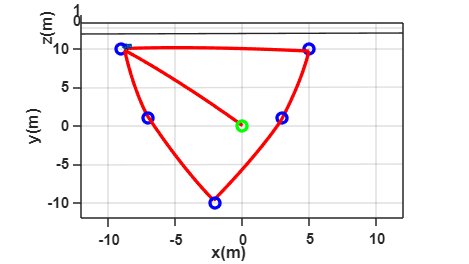



%%Control Lazo Abierto
clear
close all
clc

% 1. TIEMPO
tf=60;
ts=0.1;
t=0:ts:tf;
N= length(t);

% 2. CONDICIONES INICIALES
x1(1)=0;
y1(1)=0;
phi(1)=pi/2;
hx(1)=x1(1);
hy(1)=y1(1);

% 3. TRAJECTORIA CON WAYPOINTS
hx_obj = [-9, -7, -2, 3, 5, -9];
hy_obj = [10,  1, -10, 1, 10, 10];
num_etapas = length(hx_obj);
etapa = 1;

% 4. GANANCIAS
Kp_lin = 1.35;
Kp_ang = 2.32;
% 5. PARÁMETROS DE CONTROL
fase = "giro";  % "giro" o "avance"
tol_ang = deg2rad(5);  % tolerancia angular para considerar que ya está alineado
tol_pos = 0.4;         % tolerancia de posición para cambio de etapa

% 6. BUCLE PRINCIPAL
for k=1:N 
    if etapa > num_etapas
        v(k)=0;
        w(k)=0;
        x1(k+1)=x1(k);
        y1(k+1)=y1(k);
        phi(k+1)=phi(k);
        hx(k+1)=hx(k);
        hy(k+1)=hy(k);
        continue
    end

    % Punto objetivo actual
    hxd = hx_obj(etapa);
    hyd = hy_obj(etapa);

    % Cálculo de errores
    dx = hxd - x1(k);
    dy = hyd - y1(k);
    rho = sqrt(dx^2 + dy^2);  % distancia
    theta = atan2(dy, dx);    % ángulo hacia el objetivo
    alpha = atan2(sin(theta - phi(k)), cos(theta - phi(k)));  % error angular normalizado [-pi, pi]

    % --- FASE DE CONTROL ---
    switch fase
        case "giro"
            v(k) = 0;
            w(k) = Kp_ang * alpha;
            if abs(alpha) < tol_ang
                fase = "avance";  % pasa a avanzar
            end
        case "avance"
            v(k) = Kp_lin * rho;
            w(k) = Kp_ang * alpha;
            if rho < tol_pos
                etapa = etapa + 1;
                fase = "giro";  % siguiente etapa, vuelve a girar
            end
    end

    % Integración
    phi(k+1) = phi(k) + w(k) * ts;
    xp1 = v(k) * cos(phi(k));
    yp1 = v(k) * sin(phi(k));
    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);

    % Registro del error
    Error(k) = rho;
end

% Ajustar longitud del vector Error
Error = [Error, repmat(Error(end), 1, length(t) - length(Error))];

% 7. GRAFICAR SIMULACIÓN
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 35]);
axis([-12 12 -12 12 0 1]);

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);
H3 = plot3(hx_obj, hy_obj, zeros(size(hx_obj)), 'bo', 'LineWidth', 2);
H4 = plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2); % punto inicial verde

step = 1;
for k = 1:step:N
    delete(H1);    
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

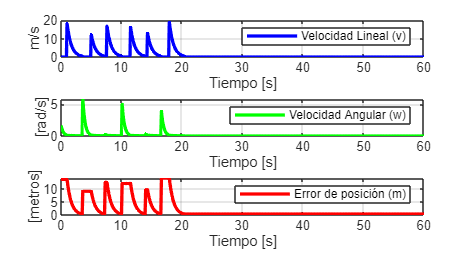


% 8. GRÁFICAS
graph = figure;
set(graph,'position',sizeScreen);
subplot(311)
plot(t, v, 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('m/s'), legend('Velocidad Lineal (v)');
subplot(312)
plot(t, w, 'g', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('Velocidad Angular (w)');
subplot(313)
plot(t, Error, 'r', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('[metros]'), legend('Error de posición (m)');

## Control de Trayectoria (Lazo cerrado con posiciones y velocidades deseadas)

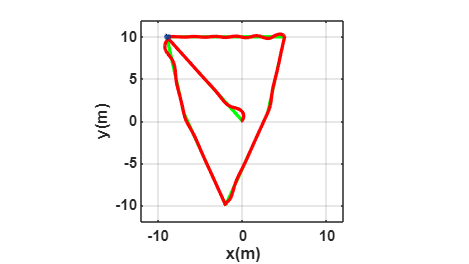



clearvars    


tf=35;
ts=0.05;
t=0:ts:tf;
N= length(t);

x1(1)=0;
y1(1)=0;
phi(1)=0;

hx(1)= x1(1);
hy(1)= y1(1);

% --- DEFINICIÓN DE PUNTOS DE LA TRAYECTORIA ---
hx_pts = [0, -9, -7, -2, 3, 5, -9];
hy_pts = [0, 10,  1, -10, 1, 10, 10];
segs = length(hx_pts)-1;

% Interpolación
hxd = zeros(1,N);
hyd = zeros(1,N);
idx = floor(N / segs);
for i = 1:segs
    i_start = (i-1)*idx + 1;
    i_end = i*idx;
    if i == segs
        i_end = N;
    end
    hxd(i_start:i_end) = linspace(hx_pts(i), hx_pts(i+1), i_end-i_start+1);
    hyd(i_start:i_end) = linspace(hy_pts(i), hy_pts(i+1), i_end-i_start+1);
end

hxdp = gradient(hxd, ts);
hydp = gradient(hyd, ts);

for k=1:N 
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    he= [hxe(k);hye(k)];
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];
    K = [3 0; 0 15];  % antes 13
    hdp=[hxdp(k);hydp(k)];

    qpRef= pinv(J)*(hdp + K*he);
    v(k)= qpRef(1);
    w(k)= qpRef(2);

    phi(k+1)=phi(k)+w(k)*ts;
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
    x1(k+1)=x1(k)+ ts*xp1;
    y1(k+1)=y1(k)+ ts*yp1;
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
end

scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 90]);
axis([-12 12 -12 12 0 1]);

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2);

step=1;
for k=1:step:N
    delete(H1);    
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

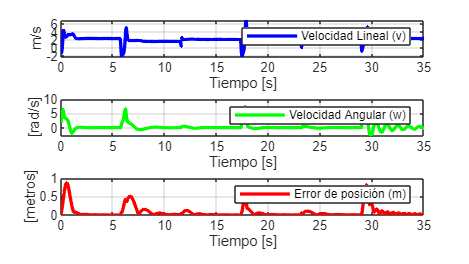


graph=figure;
set(graph,'position',sizeScreen);
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## Control en Lazo Abierto

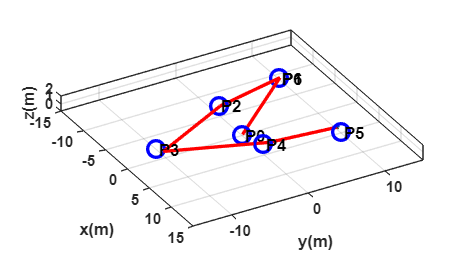


clearvars    % <

tf = 70;
ts = 0.1;
t = 0: ts: tf;
N = length(t);

% --- VARIABLES DE ESTADO ---
x1 = zeros(1,N+1);
y1 = zeros(1,N+1);
phi = zeros(1,N+1);
x1(1) = 0; y1(1) = 0; phi(1) = 0;

hx = zeros(1,N+1);
hy = zeros(1,N+1);
hx(1) = x1(1);
hy(1) = y1(1);

% --- VELOCIDADES U Y W ---
u = zeros(1,N);
w = zeros(1,N);

% --- FUNCIÓN AUXILIAR DE DURACIÓN ---
dur = @(segundos) floor(segundos/ts);
i = 1;

% === TRAMO 1: (0,0) → (−9,10) ===
w(i:i+dur(4.58)) = 0.5; i = i + dur(4.58);
u(i:i+dur(13.45)) = 1; i = i + dur(13.45);

% === TRAMO 2: (−9,10) → (−7,1) ===
w(i:i+dur(5.28)) = 0.5; i = i + dur(5.28);
u(i:i+dur(9.22)) = 1; i = i + dur(9.22);

% === TRAMO 3: (−7,1) → (−2,−10) ===
w(i:i+dur(0.4)) = 0.5; i = i + dur(0.4);
u(i:i+dur(12.08)) = 1; i = i + dur(12.08);

% === TRAMO 4: (−2,−10) → (3,1) ===
w(i:i+dur(4.6)) = 0.5; i = i + dur(4.6);
u(i:i+dur(12.08)) = 1; i = i + dur(12.08);

% === TRAMO 5: (3,1) → (5,10) ===
w(i:i+dur(0.4)) = 0.5; i = i + dur(0.4);
u(i:i+dur(9.22)) = 1; i = i + dur(9.22);

% === TRAMO 6: (5,10) → (−9,10) ===
w(i:i+dur(3.58)) = 0.5; i = i + dur(3.58);
u(i:i+dur(14)) = 1; i = i + dur(14);

u = u(1:N);
w = w(1:N);


% --- SIMULACIÓN DE MOVIMIENTO ---
for k = 1:N 
    phi(k+1) = phi(k) + w(k)*ts;
    xp1 = u(k)*cos(phi(k));
    yp1 = u(k)*sin(phi(k));
    x1(k+1) = x1(k) + xp1*ts;
    y1(k+1) = y1(k) + yp1*ts;
    hx(k+1) = x1(k+1); 
    hy(k+1) = y1(k+1);
end

% --- SIMULACIÓN ANIMADA 3D ---
scene = figure;
set(scene, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
sizeScreen = get(0,'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');

axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([60 30]);                         
axis([-15 15 -15 15 0 2]);              %

% --- INICIAR ROBOT Y TRAZADO DE RUTA ---
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0.1*ones(1,1), 'r', 'LineWidth', 2); 

% --- PUNTOS OBJETIVO Y ETIQUETAS ---
puntos = [0 0;
          -9 10;
          -7 1;
          -2 -10;
          3 1;
          5 10;
          -9 10];

for p = 1:size(puntos,1)
    plot3(puntos(p,1), puntos(p,2), 0.1, 'bo', 'MarkerSize', 10, 'LineWidth', 2);
    text(puntos(p,1)+0.5, puntos(p,2), 0.2, ['P' num2str(p-1)], 'FontSize', 10, 'FontWeight', 'bold');
end

% --- ANIMACIÓN EN TIEMPO REAL ---
step = 1;
for k = 1:step:N
    delete(H1);    
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), 0.1*ones(1,k), 'r', 'LineWidth', 2);  
    pause(ts);
end

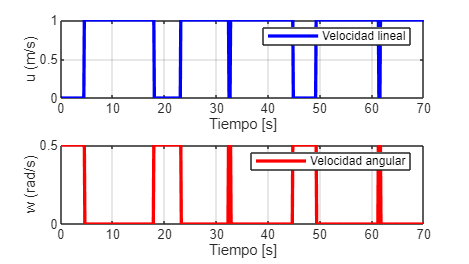


% --- GRÁFICAS DE U Y W ---
graph = figure;
set(graph,'position',sizeScreen);
subplot(2,1,1)
plot(t(1:length(u)), u, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('u (m/s)'), legend('Velocidad lineal');

subplot(2,1,2)
plot(t(1:length(w)), w, 'r', 'LineWidth', 2), grid on

xlabel('Tiempo [s]'), ylabel('w (rad/s)'), legend('Velocidad angular');